
clear


M0=1;

% 设置 phi 和 D 的范围（0到0.5/1，步长为 0.01）

phi_vals = 0.01:0.01:0.99;
%D_vals = 0.01:0.01:0.99;
D_vals = 0.01:0.01:0.5;

% 初始化一个空矩阵来存储 Irms 数据
irms = zeros(length(phi_vals), length(D_vals)); 

% 计算每个 (phi, D) 对应的 Irms
for phi_idx = 1:length(phi_vals)
    for D_idx = 1:length(D_vals)
        phi = phi_vals(phi_idx);
        D = D_vals(D_idx);
        % 调用函数，返回 Irms 和 P 值，这里只需要 Irms
        [Irms, ~] = RMScurrent_Power_ForwardTPCMode220241226(phi, D, M0);
        irms(phi_idx, D_idx) = Irms;% 确保数据顺序与 D_vals 和 phi_vals 对应
    end
end


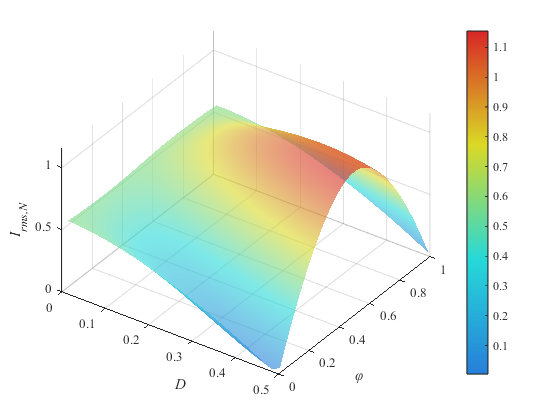

% 创建网格数据用于绘制 3D 图形
[x, y] = meshgrid(D_vals,phi_vals);



% 绘制 3D 曲面图
figure;
surf(x, y, irms, 'EdgeColor', 'none', 'FaceAlpha', 0.6);
xlim([0, 0.5]);
ylim([0, 1]);
shading interp;  % 设置渐变阴影

% 定义颜色分辨率
n = 256;

% 原始颜色渐变 (浅蓝色->绿色->黄色->红色)
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红

% 降低饱和度
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度

% 应用自定义 colormap
colormap(desaturated_cmap);
colorbar;

%title('\it{i}_{rms} versus \it{D} and ϕ ')
xlabel('\it{D}', 'FontName', 'Times New Roman');
ylabel('\it{φ}', 'FontName', 'Times New Roman');
zlabel('\it{I}_{rms,N}', 'FontName', 'Times New Roman');

% 设置字体为新罗马字体
set(gca, 'FontName', 'Times New Roman');

grid on
view(35, 45); % 设置视角

hold on;  % 保持图像以绘制多个标记

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'Irms varies from D and phi.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');


% % 遍历D_vals来找到每行的局部最小值
% for D_idx = 1:length(D_vals)
%     % 找到最小值的位置，注意反向寻找最小值
%     [minpeaks, minlocs] = findpeaks(-irms(D_idx, :));  % 反向寻找最小值
% 
%     % 获取对应的 x, y, z 坐标
%     min_x = x(D_idx, minlocs);  % 获取minlocs对应的x坐标
%     min_y = y(minlocs, D_idx);  % 获取minlocs对应的y坐标
%     min_z = -minpeaks;  % 对应的最小值z坐标（反向）
% 
%     % 绘制局部最小值点
%     plot3(min_x, min_y, min_z, '^', 'Color', [25/256, 215/256, 25/256], 'MarkerFaceColor', [25/256, 215/256, 25/256]);
% end
% 
% % 显示图例条目，所有局部最小值共享同一个图例条目
% legend('Local Minima of \it{I}_{rms}', 'Location', 'best');  % 将所有局部最小值归为一个条目
% 
% % 设置字体为新罗马字体
% set(gca, 'FontName', 'Times New Roman');
